% THE GOAL OF THIS SCRIPT IS TO BE EASILY EDITABLE SO THAT THE SAME
% ANALYSIS CAN BE DONE FOR VARIOUS MATERIALS
% Look for //CHANGE// to know where to manipulate the code
% ATTRIBUTION: ChatGPT, Mathworks.com

% Open .csv files and retrieve data
% //CHANGE// the filename and filepath to the location and name of file to open
filename = '/Users/vinay/Downloads/Brass_1_1.csv';
data = readtable(filename,'HeaderLines',5);

% Define material properties
% //CHANGE// for your specific sample
width = 15.19;
thickness = 3.18;
length = 70.69;

% Extract data from tables
% //CHANGE// to the correct indices in .csv file
time = data{3:1325, 2};
displacement = data{3:1325, 3};
force = data{3:1325, 4};

% Calculate engineering stress and strain values for each material and tabularize
egrstress = force ./ (width * thickness); 
egrstrain = displacement ./ length; 
table1 = table(time,egrstrain,egrstress);
disp(table1);

     time     egrstrain     egrstress
    ______    __________    _________

         0             0     32.945  
       0.1    5.2341e-05     34.541  
     0.187    0.00018249      39.73  
      0.22    0.00032112     45.044  
      0.25    0.00046683     50.355  
      0.29    0.00062809     55.596  
     0.389    0.00090678     60.778  
     0.466     0.0011402     65.956  
     0.545     0.0013892     71.137  
     0.635      0.001648     76.339  
     0.718     0.0018984     81.572  
     0.806      0.002163     86.792  
     0.898     0.0024261     91.994  
     0.978     0.0026835     97.187  
     1.075     0.0029679     102.41  
     1.166     0.0032381     107.62  
      1.26     0.0035196     112.79  
     1.356     0.0037997     117.99  
     1.444      0.004077     123.17  
     1.544     0.0043698     128.23  
     1.639     0.0046541     133.44  
     1.739     0.004951


% Create a subset containing only the values from elastic deformation,
% //CHANGE// go through table and .csv file to find correct indices to use
subset_strain = egrstrain(1:54);
subset_stress = egrstress(1:54);

% Perform linear regression to calculate the slope and intercept
coefficients = polyfit(subset_strain, subset_stress, 1);
slope = coefficients(1);
disp(['Young''s Modulus (E): ', num2str(slope),' MPa']);

Young's Modulus (E): 15295.8505 MPa


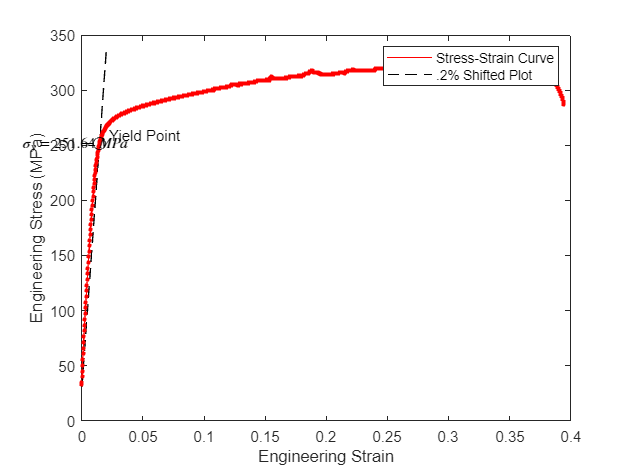


% Create a set of x-values for the straight line with the desired slope
x_values = subset_strain + 0.002;
y_values = slope * x_values;

% Extend the range of x-values for the dotted line
% //CHANGE// if the intersection point occurs near zero on the x-axis or
% somewhere else that's unintended
extended_x_values = 0:0.001:0.02; % Modify the range and increment as needed
extended_y_values = slope * (extended_x_values + 0.002);

% Find the intersection point using fminbnd with the difference function,
% this was all done by ChatGPT and I don't understand it at all :/
% IF it isn't working properly, //CHANGE// by asking ChatGPT lol
difference_function = @(x) abs(interp1(egrstrain, egrstress, x) - (slope * (x + 0.002)));
initial_guess = 0.01; % Start searching around this x-coordinate
search_range = [0, 0.02]; % Adjust the search range as needed
options = optimset('TolX', 1e-6); % Adjust tolerance for better accuracy
intersection_x = fminbnd(difference_function, search_range(1), search_range(2), options);
intersection_y = interp1(egrstrain, egrstress, intersection_x);

% Plot the original curve and the offset curve
figure;
p1 = plot(egrstrain, egrstress, 'Color', 'red');
hold on
shifted_plot = plot(extended_x_values, extended_y_values, 'LineStyle', '--', 'Color', 'black');
scatter(egrstrain, egrstress, 5, 'filled', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');

% Plot and label the intersection point (Yield Point)
plot(intersection_x, intersection_y, 'Marker', 'o', 'Color', 'black', 'MarkerSize', 8, 'DisplayName', 'Yield Point');
text(intersection_x + .0075, intersection_y, 'Yield Point', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');

% Add a horizontal dashed line at the intersection y-value for the Yield Strength  
plot([0, intersection_x], [intersection_y, intersection_y], 'k--'); % 'k--' for black dashed line
text(-.05, intersection_y, ['$$\sigma_y = ' num2str(intersection_y, '%.2f') '\, MPa$$'], 'Interpreter', 'latex');

% Customize the appearance of the lines as needed
xlabel('Engineering Strain');
ylabel('Engineering Stress (MPa)'); 
legend('Stress-Strain Curve','.2% Shifted Plot');

hold off